# Abgabe Numerik Programmierblatt 1

## Matthias Gültig - Matrikelnummer: 3469020 

Aufgabe 1 - Euler (siehe function)

Aufgabe 1 - Heun (siehe function)

Aufgabe 1 - Runge-Kutta (siehe function)

Aufgabe 2a)

Räuber Beute DGL

Aufgabe 2a) Visualisierungen

%{
initialisiere Parameter
Intervall I = [0,T]
Anfangswert y0 in IR^d 
Zeitschritte tau in IR^+
%}

y_0 = [0.5; 0.5];
T = 20;

%Initialisiere Zeitschritte
tau1 = 0.64;
tau2 = 0.32;
tau3 = 0.16;
tau4 = 0.08;
tau5 = 0.04;


%{
rufe Funktionen für verschiedene taus auf. Im Beispiel tau1 und tau 5
solExplEuler: Lösungsmatrix vom Euler
solExplHeun: Lösungsmatrix vom Heun
%}
solExplEulerTau1 = explicit_euler(@rabeu, y_0, T, tau1)

solExplEulerTau1 = 	1.0e+158 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    6.0330       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -6.0330      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf


solExplHeunTau1 = explicit_heun(@rabeu, y_0, T, tau1)

solExplHeunTau1 =     0.5000    0.7600    1.1767    1.7341    2.0333    1.2125    0.8382    0.7254    0.7402    0.8402    0.9994    1.1705    1.2565    1.1688    0.9898    0.8682    0.8374    0.8784    0.9667    1.0681    1.1325    1.1158    1.0324    0.9482    0.9079    0.9170    0.9625    1.0222    1.0669    1.0717    1.0357    0.9861
    0.5000    0.4000    0.3903    0.5438    1.1318    2.0696    1.3395    1.1098    0.9210    0.8005    0.7613    0.8191    0.9811    1.1722    1.2213    1.1286    1.0047    0.9076    0.8620    0.8795    0.9578    1.0610    1.1184    1.0968    1.0309    0.9645    0.9246    0.9235    0.9604    1.0168    1.0588    1.0621


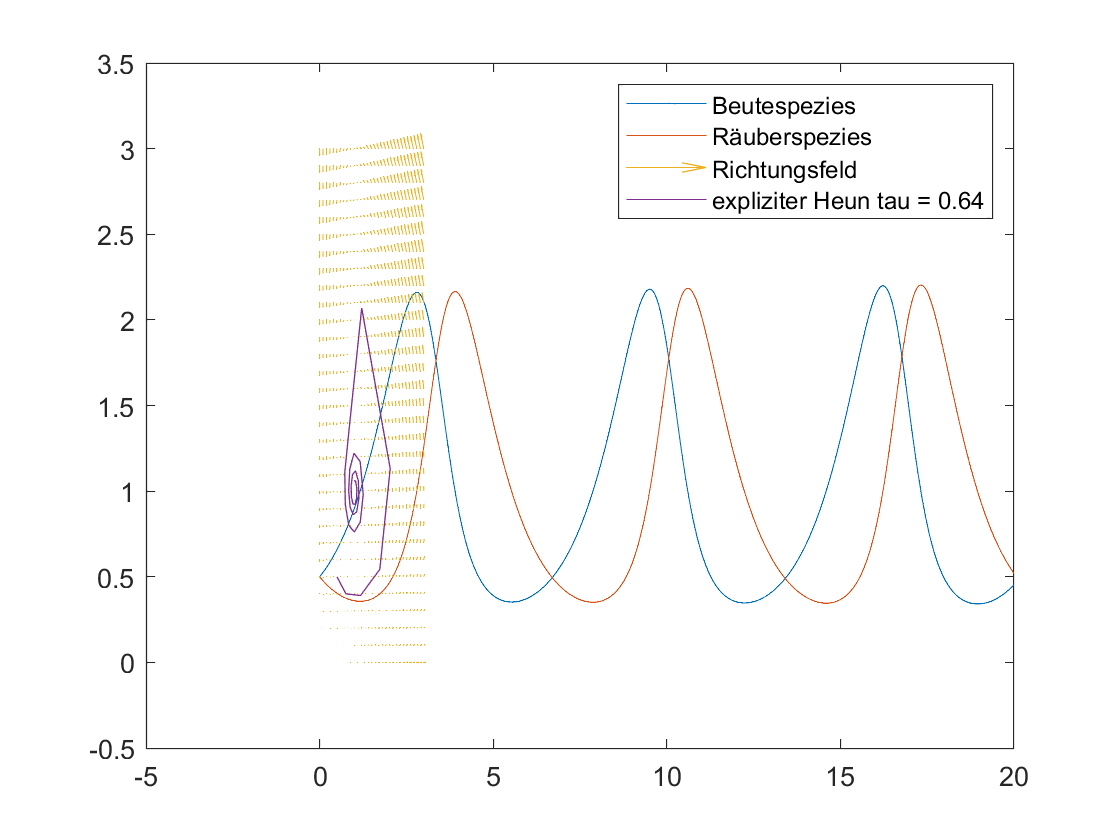


% visualisiere Lösungskurven -> tau zu groß!!
[x,y] = meshgrid(0:0.1:3,0:0.1:3);
dx = (1-y).*x;
dy = (x-1).*y;
quiver(x,y,dx,dy, 'DisplayName', 'Richtungsfeld');
hold on;
plot(solExplHeunTau1(1,:), solExplHeunTau1(2,:), 'DisplayName', 'expliziter Heun tau = 0.64');
hold on;
legend;
hold off;

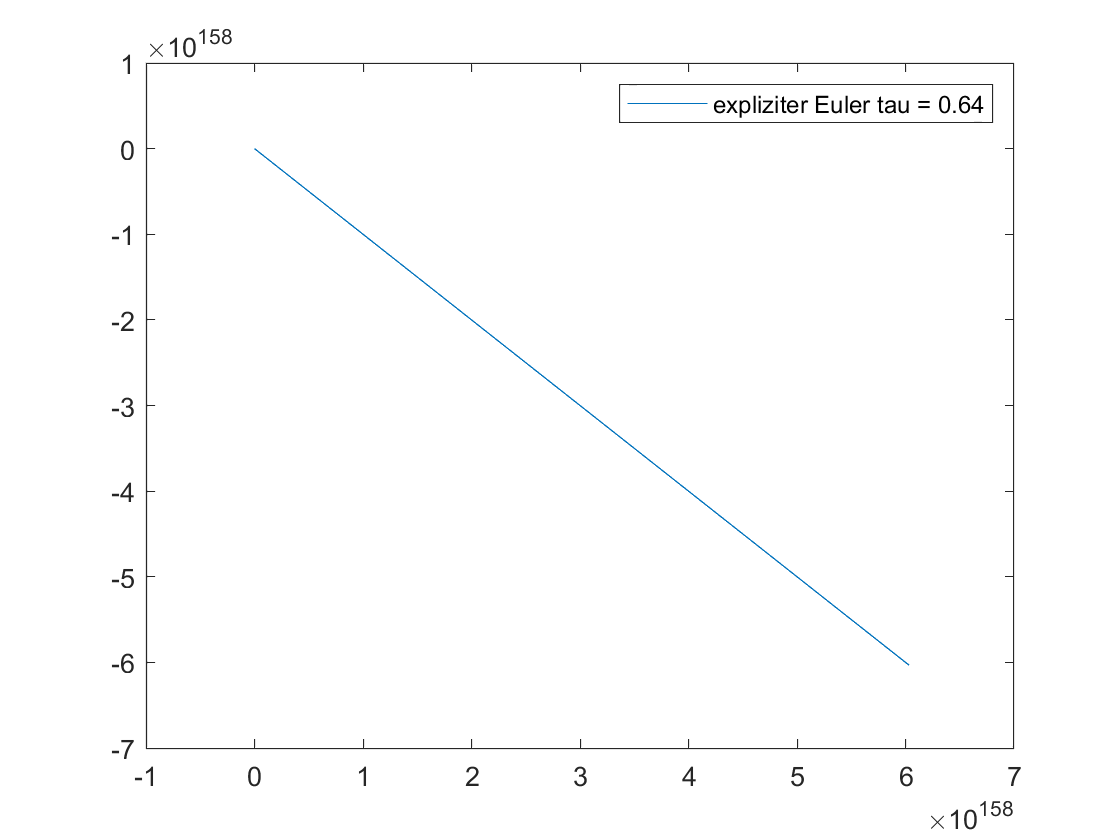


plot(solExplEulerTau1(1,:), solExplEulerTau1(2,:), 'DisplayName', 'expliziter Euler tau = 0.64');
legend;
hold off;


% visualisiere Lösungskurven
solExplEulerTau5 = explicit_euler(@rabeu, y_0, T, tau5)

solExplEulerTau5 =     0.5000    0.5100    0.5204    0.5312    0.5425    0.5541    0.5662    0.5788    0.5918    0.6053    0.6192    0.6337    0.6486    0.6640    0.6800    0.6965    0.7135    0.7311    0.7493    0.7680    0.7873    0.8072    0.8277    0.8488    0.8706    0.8930    0.9160    0.9396    0.9640    0.9889    1.0146    1.0409    1.0679    1.0956    1.1239    1.1530    1.1826    1.2130    1.2440    1.2756    1.3079    1.3408    1.3742    1.4082    1.4427    1.4777    1.5132    1.5490    1.5852    1.6216
    0.5000    0.4900    0.4804    0.4712    0.4623    0.4539    0.4458    0.4381    0.4307    0.4236    0.4170    0.4106    0.4046    0.3989    0.3935    0.3885    0.3838    0.3794    0.3753    0.3715    0.3681    0.3650    0.3621    0.3597    0.3575    0.3556    0.3541    0.3529    0.3521    0.3516    0.3514    0.3516    0.3522    0.3531    0.3545    0.3562    0.3584    0.3610    0.3641    0.3677    0.3717    0.3763    0.3814    0.3871    0.3935    0.4004    0.4081    0.4165

solExplHeunTau5 = explicit_heun(@rabeu, y_0, T, tau5)

solExplHeunTau5 =     0.5000    0.5162    0.5331    0.5505    0.5684    0.5870    0.6062    0.6259    0.6463    0.6672    0.6888    0.7110    0.7337    0.7571    0.7810    0.8054    0.8303    0.8557    0.8816    0.9079    0.9345    0.9614    0.9885    1.0158    1.0432    1.0705    1.0977    1.1247    1.1513    1.1775    1.2030    1.2278    1.2518    1.2747    1.2964    1.3169    1.3359    1.3534    1.3692    1.3833    1.3955    1.4059    1.4144    1.4209    1.4256    1.4284    1.4294    1.4287    1.4264    1.4226
    0.5000    0.4938    0.4878    0.4823    0.4771    0.4722    0.4677    0.4637    0.4600    0.4567    0.4538    0.4514    0.4494    0.4480    0.4470    0.4465    0.4466    0.4472    0.4484    0.4503    0.4528    0.4560    0.4598    0.4645    0.4699    0.4762    0.4833    0.4913    0.5002    0.5101    0.5210    0.5329    0.5458    0.5597    0.5747    0.5908    0.6078    0.6259    0.6449    0.6647    0.6854    0.7068    0.7288    0.7513    0.7741    0.7972    0.8204    0.8435 

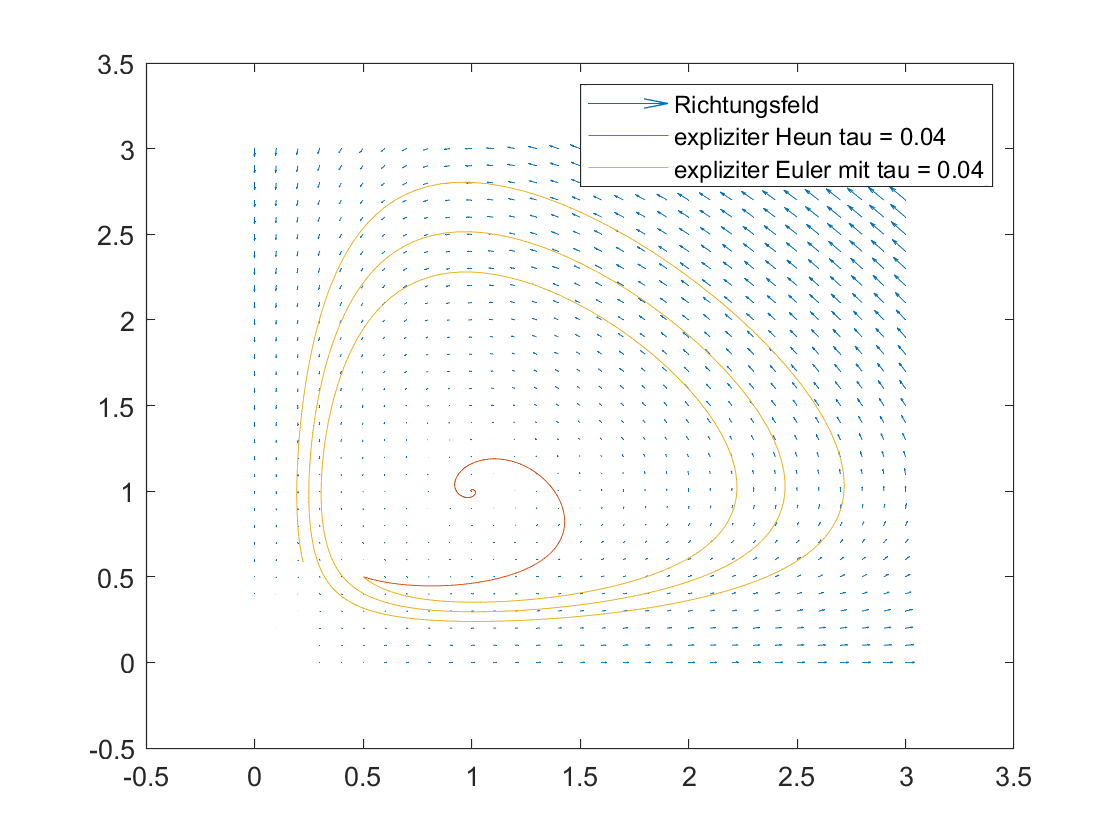

[x,y] = meshgrid(0:0.1:3,0:0.1:3);
dx = (1-y).*x;
dy = (x-1).*y;

quiver(x,y,dx,dy, 'DisplayName', 'Richtungsfeld');
hold on;
plot(solExplHeunTau5(1,:), solExplHeunTau5(2,:), 'DisplayName', 'expliziter Heun tau = 0.04');
hold on;
plot(solExplEulerTau5(1,:), solExplEulerTau5(2,:), 'DisplayName', 'expliziter Euler mit tau = 0.04');
hold on;
legend;
hold off;

Aufgabe 2b) 

x = (0:tau:T)

x =          0    0.0040    0.0080    0.0120    0.0160    0.0200    0.0240    0.0280    0.0320    0.0360    0.0400    0.0440    0.0480    0.0520    0.0560    0.0600    0.0640    0.0680    0.0720    0.0760    0.0800    0.0840    0.0880    0.0920    0.0960    0.1000    0.1040    0.1080    0.1120    0.1160    0.1200    0.1240    0.1280    0.1320    0.1360    0.1400    0.1440    0.1480    0.1520    0.1560    0.1600    0.1640    0.1680    0.1720    0.1760    0.1800    0.1840    0.1880    0.1920    0.1960


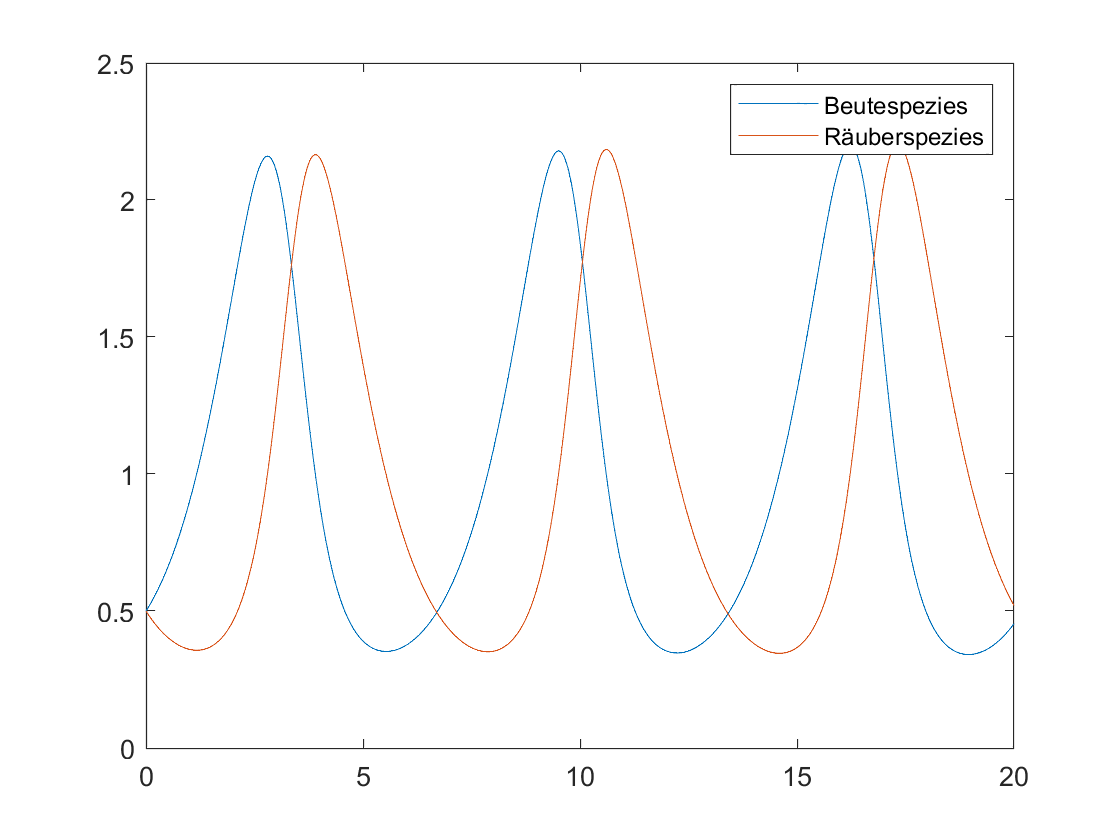

plot(x,solExplEuler(1,:),'DisplayName', 'Beutespezies');
hold on
plot(x,solExplEuler(2,:),'DisplayName', 'Räuberspezies');
legend;
hold off;

Aufgabe 2c)

Euler hat Probleme bei zu großer Zeitschrittweite -> schlecht konditioniert?

Stataionäre DGL kommt bei Euler zum Tragen

Aufgabe 3

a)